figure('Visible','on')

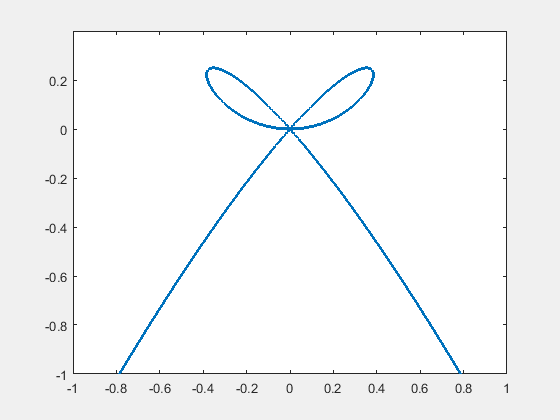

cmh = uicontextmenu;
uimenu(cmh,'Label', 'Red', 'Callback', {@setcolor, 'r'});
uimenu(cmh,'Label', 'Green', 'Callback', {@setcolor, 'g'});
uimenu(cmh,'Label', 'Black', 'Callback', {@setcolor, 'k'});
h = fimplicit(@(x,y) x.^4-x.^2.*y+y.^3 ,[-1 1 -1 0.4], 'UIContextMenu', cmh);
h.LineWidth =2;

h.UIContextMenu = cmh;

function setcolor(~, ~, color) 
    % Callback function for the uimenu "color"
    
    h = gco; % Get the current object
    h.Color = color;
end